## 1.0 Importing subject EEG

clear;clc;
% --- paths (use your original logic) ---
if exist('I:\', 'dir')
    input_path = 'I:\My Drive\Data\New Data\EEG epoched\';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

conditions = {'BLT'}; %,'BLT','P1','P2','P3'
num_ch = 32;
expected_num_time = 1792; % sample count per epoch (your value)
fs = []; % will set from EEG.srate on first load

## 1.1 Load and import file as EEGLAB matrix

% Concatenate beta-band filtered data across conditions and trials:
% beta_concat = [];        % will be channels x totalSamples
trial_ranges = [];       % Nx2 start/end indices in concatenated samples
trial_info = {};         % optional: store [condition, trialIndexInCondition]


condition = conditions{1};
in_dir = fullfile(input_path, condition);
set_files = dir(fullfile(in_dir, '*.set'));
names = cellstr({set_files.name})';
set_files_sorted = sort(names);
if isempty(set_files)
    fprintf('No .set files for %s — skipping\n', condition);
end

EEG = pop_loadset(fullfile(in_dir, set_files_sorted{10}));

pop_loadset(): loading file I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.set ...


Reading float file 'I:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


if isempty(fs), fs = EEG.srate; end

% choose odd/even indexing as in your pipeline
if ismember(condition, {'BLA','P1','P2','P3'})
    epoch_trials = 1:2:EEG.trials;
else
    epoch_trials = 2:2:EEG.trials;
end

data = EEG.data(:, :, epoch_trials); % channels x time x trials
nTrials = size(data,3);
nTime = size(data,2);

fprintf('EEG size: channels x samples = %d x %d\n x %d \n', size(data,1), size(data,2), size(data,3));

EEG size: channels x samples = 32 x 1792
 x 60 


## 1.2 Visualizing the EEG for the first trial

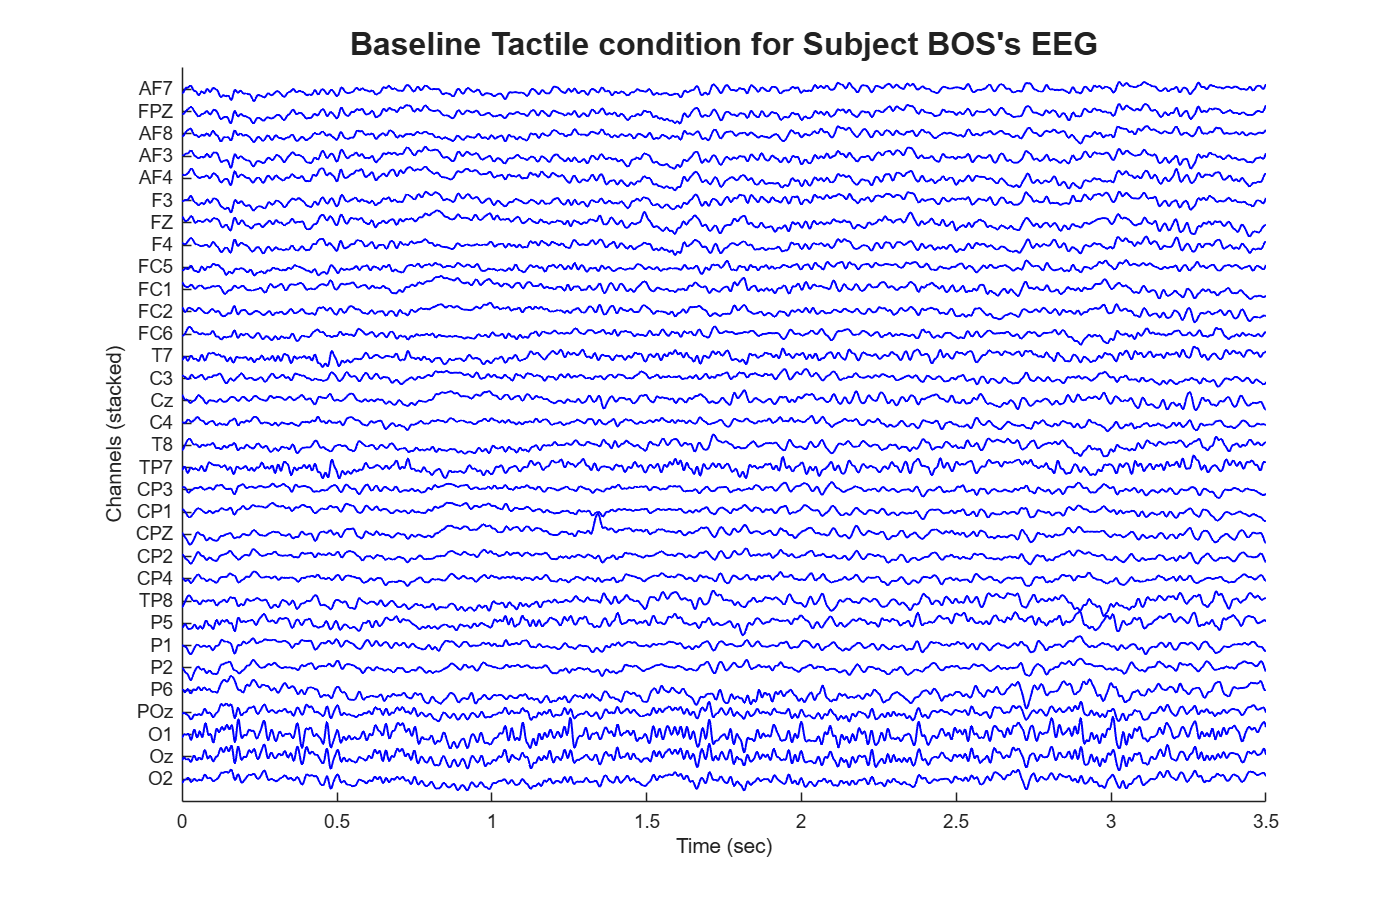

num_channels_plot = 32;
T_subject = 3.5; % duration of each trial
display_channels = 1:1:num_channels_plot;
display_channels_str = {EEG.chanlocs.labels};
figure('Position',[50 50 1400 900])
offset = 30; % vertical spacing between channels
hold on
time_ms_eeg = linspace(0, T_subject, nTime); % time in seconds

for ch = 1:num_channels_plot
    % Plot each channel stacked upward directly from the 3D 'data' array
    plot(time_ms_eeg, squeeze(data(ch, :, 1)) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.5);
end
hold off

xlim([0 3.5]);
ylim([-offset, num_channels_plot*offset]);

xlabel('Time (sec)');
ylabel('Channels (stacked)');
tick_positions = (num_channels_plot - display_channels) * offset;
yticks(flip(tick_positions));
% Flip the ytick labels so channel 1 appears at the top
yticklabels(flip(string(display_channels_str)));
set(gca,'FontSize',14);
title('Baseline Tactile condition for Subject BOS''s EEG','FontSize',24);

## 2.0 Parameter setup for CVAE

% 0. Define the time window of interest and crop the data!
% Find indices where time is between 0.380 and 0.860 seconds
valid_time_idx = time_ms_eeg >= 0.380 & time_ms_eeg < 0.860;

% Crop the time vector and the main EEG data array
time_cropped = time_ms_eeg(valid_time_idx);
data_cropped = data(:, valid_time_idx, :); 
nTime_cropped = size(data_cropped, 2);

fprintf('Cropped data from %d to %d time samples per trial.\n', size(data, 2), nTime_cropped);

Cropped data from 1792 to 246 time samples per trial.



% 1. Create the Condition Vector (C) for a SINGLE cropped trial
numClasses = 4;
C_trial = zeros(numClasses, nTime_cropped);

% Assign the 120ms bins using the cropped time vector
C_trial(1, time_cropped >= 0.380 & time_cropped < 0.500) = 1; % Before Stimulus
C_trial(2, time_cropped >= 0.500 & time_cropped < 0.620) = 1; % Tactile Stimulus
C_trial(3, time_cropped >= 0.620 & time_cropped < 0.740) = 1; % After Tactile Stimulus
C_trial(4, time_cropped >= 0.740 & time_cropped < 0.860) = 1; % After Stimulus

% 2. Split data by whole trials (80% Train, 20% Test)
num_train_trials = floor(0.8 * nTrials);

% Shuffle trials randomly
rng(42); % Set random seed for reproducibility
idx_rand = randperm(nTrials);
train_idx = idx_rand(1:num_train_trials);
test_idx = idx_rand(num_train_trials+1:end);

% USE THE CROPPED DATA HERE
data_train = data_cropped(:, :, train_idx);
data_test = data_cropped(:, :, test_idx);

% 3. Reshape into 2D matrices for the network (Channels x [Time * Trials])
X_train = reshape(data_train, num_ch, []);
X_test = reshape(data_test, num_ch, []);

% 4. Replicate the Condition vector across all train and test trials
C_train = repmat(C_trial, 1, length(train_idx));
C_test = repmat(C_trial, 1, length(test_idx));

% 5. Define CVAE Configuration
r = rank(X_train);
cfg.method = "ivae"; % "cvae" Or "ivae"
cfg.bottleneckSize = r - 2; 
cfg.encoderLayerSizes = [64, 32];
cfg.decoderLayerSizes = [32, 64];
cfg.priorLayerSizes = [16];
cfg.epochs = 500;      % Keeping our early stopping setup!
cfg.patience = 5;
cfg.batchSize = 26;
cfg.learnRate = 1e-3;

## 2.1 Run CVAE for subject data

fprintf('Training CVAE model with early stopping...\n');

Training CVAE model with early stopping...


% Notice we are passing X_test and C_test now
[encNet, decNet, priorNet, info] = trainEEGCVAE(X_train, C_train, X_test, C_test, cfg);

Epoch 1/500 - Train Loss: 698.5963 | Val Loss: 352.9133
Epoch 2/500 - Train Loss: 305.9111 | Val Loss: 267.7279
Epoch 3/500 - Train Loss: 248.8836 | Val Loss: 224.6959
Epoch 4/500 - Train Loss: 210.4427 | Val Loss: 200.8037
Epoch 5/500 - Train Loss: 191.9177 | Val Loss: 186.5767
Epoch 6/500 - Train Loss: 179.5814 | Val Loss: 175.8774
Epoch 7/500 - Train Loss: 169.6718 | Val Loss: 166.9242
Epoch 8/500 - Train Loss: 161.7983 | Val Loss: 160.1940
Epoch 9/500 - Train Loss: 154.8964 | Val Loss: 152.8850
Epoch 10/500 - Train Loss: 149.2089 | Val Loss: 148.3494
Epoch 11/500 - Train Loss: 144.0588 | Val Loss: 144.8316
Epoch 12/500 - Train Loss: 139.5465 | Val Loss: 139.8037
Epoch 13/500 - Train Loss: 134.8681 | Val Loss: 134.7645
Epoch 14/500 - Train Loss: 130.3331 | Val Loss: 130.5650
Epoch 15/500 - Train Loss: 125.8641 | Val Loss: 126.6922
Epoch 16/500 - Train Loss: 122.0899 | Val Loss: 123.6460
Epoch 17/500 - Train Loss: 118.9356 | Val Loss: 120.6585
Epoch 18/500 - Train Loss: 115.7718 | Va

## 2.2 Plot Training and Validation Loss

fprintf('Plotting training and validation loss...\n');

Plotting training and validation loss...


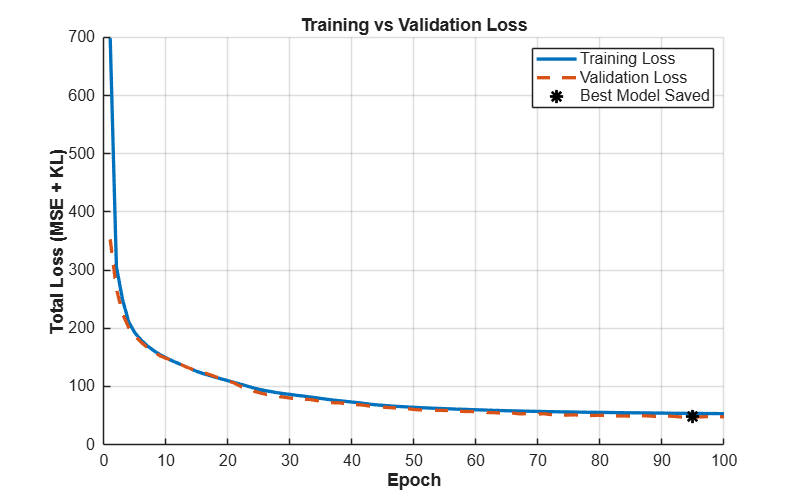

figure('Position', [150 150 800 500]);
hold on;
% Plot Train and Val loss
epochs_trained = length(info.lossHistory);
plot(1:epochs_trained, info.lossHistory, '-', 'LineWidth', 2.5, 'Color', [0 0.4470 0.7410], 'DisplayName', 'Training Loss');
plot(1:epochs_trained, info.valLossHistory, '--', 'LineWidth', 2.5, 'Color', [0.8500 0.3250 0.0980], 'DisplayName', 'Validation Loss');

% Mark the best epoch (where the weights were actually saved)
[bestLoss, bestEpoch] = min(info.valLossHistory);
plot(bestEpoch, bestLoss, 'k*', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Best Model Saved');
hold off;

grid on;
legend('Location', 'northeast', 'FontSize', 12);
xlabel('Epoch', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Total Loss (MSE + KL)', 'FontSize', 14, 'FontWeight', 'bold');
title('Training vs Validation Loss', 'FontSize', 16);
set(gca, 'FontSize', 12);

## 3.0 Extract Latent Representations (Inference on Test Data)

fprintf('Extracting latent representations for the Test Set...\n');

Extracting latent representations for the Test Set...



% Convert test data to dlarray format
X_test_dl = dlarray(X_test, 'CB');
C_test_dl = dlarray(C_test, 'CB');

% Concatenate Features (X) and Conditions (C) for the Encoder
XC_test = cat(1, X_test_dl, C_test_dl);

% Forward pass through the trained encoder to get the latent mean (zMu)
[zMu_test, zLogVar_test] = forward(encNet, XC_test);

% Extract the data from the deep learning array back into standard MATLAB matrices
latent_representations = extractdata(zMu_test);

fprintf('Latent representation extracted! Size: %d x %d\n', size(latent_representations, 1), size(latent_representations, 2));

Latent representation extracted! Size: 23 x 2952


%% 4.0 Visualizing Latent Space (Latent 1 vs. Others)
fprintf('Visualizing latent representations...\n');

Visualizing latent representations...


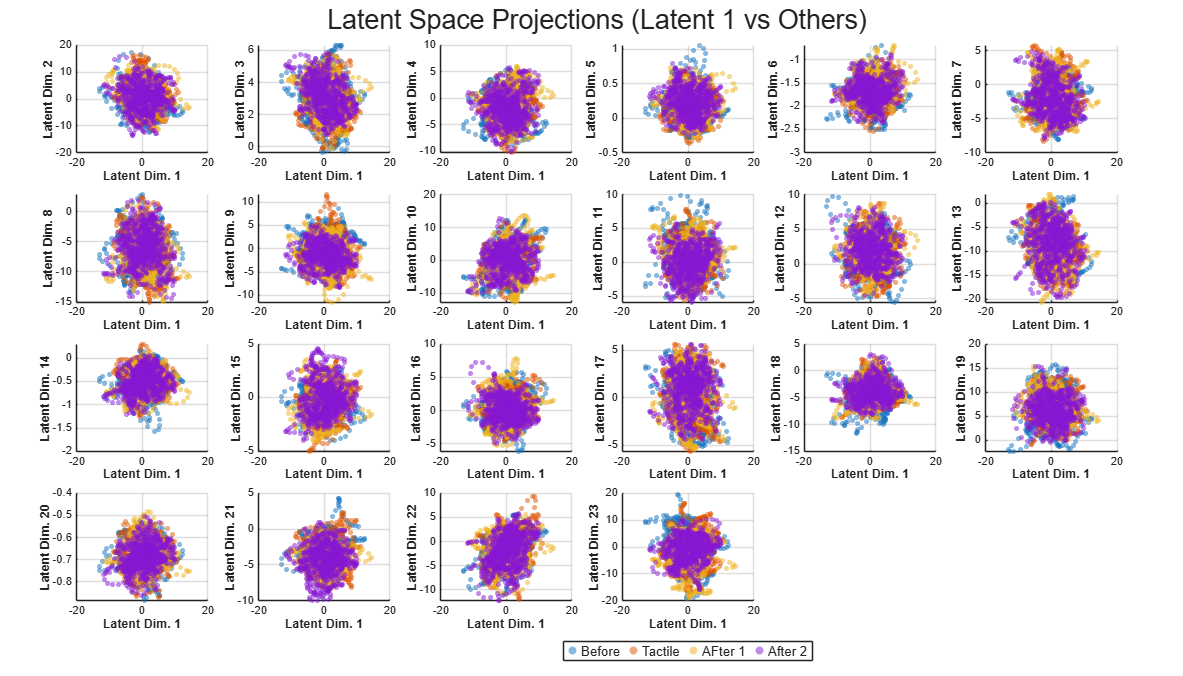


% 1. Convert one-hot encoded C_test back to categorical indices (1 to 4)
[~, condition_idx] = max(C_test, [], 1);
condition_names = {'Before', 'Tactile', 'AFter 1', 'After 2'};

% 2. Setup colors and figure layout
colors = lines(length(condition_names)); % Generate distinct colors
num_latents = size(latent_representations, 1);

figure('Position', [100 100 1400 800]);
% tiledlayout is perfect for dynamically creating a grid of subplots
t = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact'); 
title(t, 'Latent Space Projections (Latent 1 vs Others)', 'FontSize', 20);

% 3. Loop through latent dimensions 2 through N
for i = 2:num_latents
    nexttile;
    hold on;
    
    % Plot each condition separately so we can build a clean legend
    for c = 1:length(condition_names)
        % Find all points belonging to the current condition
        idx = (condition_idx == c); 
        
        % Scatter plot: Latent 1 on X-axis, Latent 'i' on Y-axis
        scatter(latent_representations(1, idx), latent_representations(i, idx), ...
                15, colors(c,:), 'filled', 'MarkerFaceAlpha', 0.5);
    end
    
    xlabel('Latent Dim. 1', 'FontWeight', 'bold');
    ylabel(sprintf('Latent Dim. %d', i), 'FontWeight', 'bold');
    grid on;
    
    hold off;
end
legend(condition_names, 'Orientation', 'horizontal', 'Location', 'southoutside', 'FontSize', 10);